syms theta1 theta2 theta3 l1 l2 l3;

frame1  = get_DH_matrix(l1,0,0,theta1);
frame1

$$frame1 = \left(\begin{array}{cccc} \cos\left(\theta_{1}\right) & -\sin\left(\theta_{1}\right) & 0 & l_{1}\,\cos\left(\theta_{1}\right)\\ \sin\left(\theta_{1}\right) & \cos\left(\theta_{1}\right) & 0 & l_{1}\,\sin\left(\theta_{1}\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

frame2  = get_DH_matrix(l2,0,0,theta2);
frame2

$$frame2 = \left(\begin{array}{cccc} \cos\left(\theta_{2}\right) & -\sin\left(\theta_{2}\right) & 0 & l_{2}\,\cos\left(\theta_{2}\right)\\ \sin\left(\theta_{2}\right) & \cos\left(\theta_{2}\right) & 0 & l_{2}\,\sin\left(\theta_{2}\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

frame3  = get_DH_matrix(l3,0,0,theta3);
frame3

$$frame3 = \left(\begin{array}{cccc} \cos\left(\theta_{3}\right) & -\sin\left(\theta_{3}\right) & 0 & l_{3}\,\cos\left(\theta_{3}\right)\\ \sin\left(\theta_{3}\right) & \cos\left(\theta_{3}\right) & 0 & l_{3}\,\sin\left(\theta_{3}\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

q1 = subs(frame1,[l1,theta1],[1,deg2rad(0)]);
q1

$$q1 = \left(\begin{array}{cccc} 1 & 0 & 0 & 1\\ 0 & 1 & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

q2 = subs(frame2,[l2,theta2],[1,deg2rad(45)]);
q2

$$q2 = \left(\begin{array}{cccc} \frac{\sqrt{2}}{2} & -\frac{\sqrt{2}}{2} & 0 & \frac{\sqrt{2}}{2}\\ \frac{\sqrt{2}}{2} & \frac{\sqrt{2}}{2} & 0 & \frac{\sqrt{2}}{2}\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

q3 = subs(frame3,[l3,theta3],[1,deg2rad(30)]);
q3

$$q3 = \left(\begin{array}{cccc} \frac{\sqrt{3}}{2} & -\frac{1}{2} & 0 & \frac{\sqrt{3}}{2}\\ \frac{1}{2} & \frac{\sqrt{3}}{2} & 0 & \frac{1}{2}\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

eef = q3*q2*q1;
disp(eef);

$$\begin{array}{l} \left(\begin{array}{cccc} \sigma_{1}-\frac{\sqrt{2}}{4} & -\sigma_{1}-\frac{\sqrt{2}}{4} & 0 & \frac{\sqrt{2}\,\sqrt{3}}{2}-\frac{\sqrt{2}}{2}+\frac{\sqrt{3}}{2}\\ \sigma_{1}+\frac{\sqrt{2}}{4} & \sigma_{1}-\frac{\sqrt{2}}{4} & 0 & \frac{\sqrt{2}\,\sqrt{3}}{2}+\frac{\sqrt{2}}{2}+\frac{1}{2}\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{\sqrt{2}\,\sqrt{3}}{4} \end{array}$$

disp('The EEF positions:')

The EEF positions:


disp(eef(1:3,4));

$$\left(\begin{array}{c} \frac{\sqrt{2}\,\sqrt{3}}{2}-\frac{\sqrt{2}}{2}+\frac{\sqrt{3}}{2}\\ \frac{\sqrt{2}\,\sqrt{3}}{2}+\frac{\sqrt{2}}{2}+\frac{1}{2}\\ 0 \end{array}\right)$$

**PLOT**

coord1 = q1(1:3,4);
qt = q2*q1;

$$\left(\begin{array}{cccc} \frac{\sqrt{2}}{2} & -\frac{\sqrt{2}}{2} & 0 & \sqrt{2}\\ \frac{\sqrt{2}}{2} & \frac{\sqrt{2}}{2} & 0 & \sqrt{2}\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

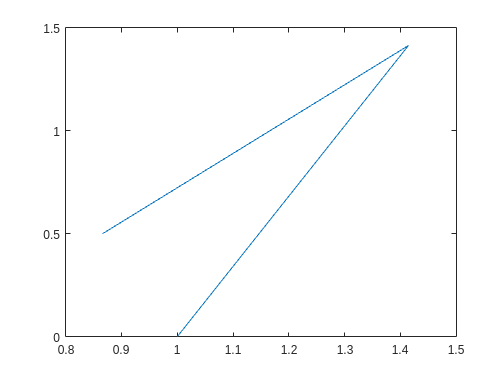

coord2 = qt(1:3,4);
coord3 = q3(1:3,4);

x = [coord1(1),coord2(1),coord3(1)];
y = [coord1(2),coord2(2),coord3(2)];
plot(x,y);

function T = get_DH_matrix(a,alpha,d,theta)
T = [cos(theta) -sin(theta)*cos(alpha) sin(theta)*sin(alpha)  a*cos(theta)
     sin(theta)  cos(theta)*cos(alpha) -cos(theta)*sin(alpha) a*sin(theta)
     0 sin(alpha) cos(alpha) d
     0 0 0 1];
end